# MATLAB Tutorial 2. Plot

## 1. Plot 기본

- 그래프 하나 그리기: plot(x1, y1, option1)

- 여러 그래프 동시에 그리기: plot(x1, y1, option1, x2, y2, option2, x3, y3, option3, ...)

- xn: 가로축 좌표

- yn: 세로축 좌표

- option: 선 스타일, 선 두께, 색상 등 그래프 스타일 지정

- 옵션 세부내용 참조: [링크](https://kr.mathworks.com/help/matlab/ref/plot.html?searchHighlight=plot&s_tid=doc_srchtitle#btzitot-LineSpec)

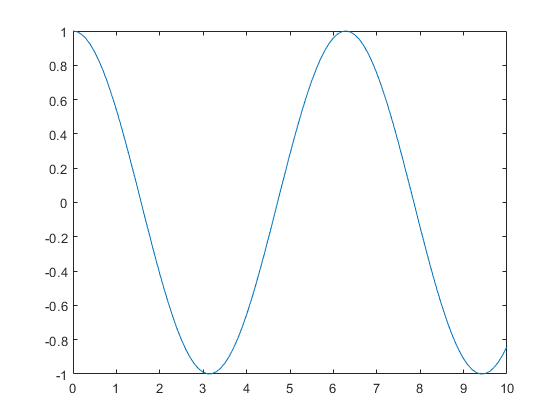

% 작업공간에 있는 모든 데이터 날리기
clc; clear; close all

x = 0:0.1:10;
y1 = cos(x);
y2 = exp(-x);

% cos(x) 그리기
plot(x, y1)

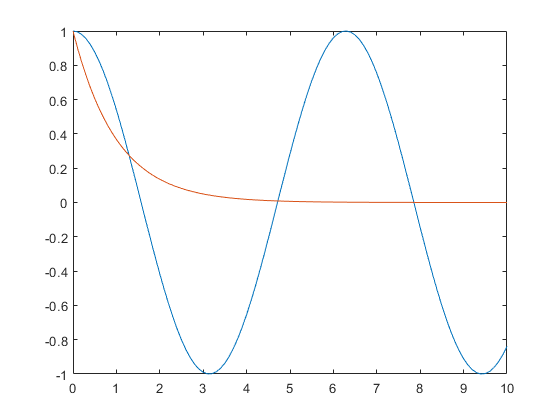

% cos(x), exp(-x) 동시에 그리기
plot(x, y1, x, y2)

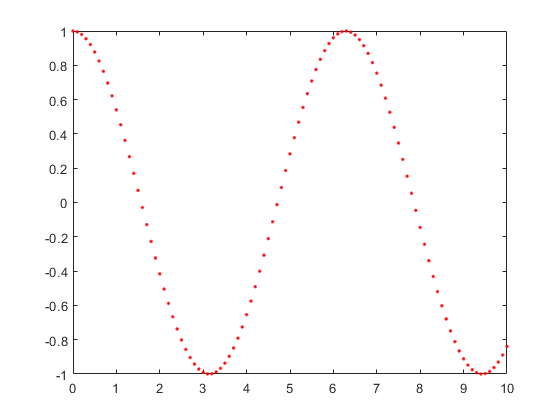

% cos(x) 빨간 점으로 그리기
plot(x, y1, 'r.')

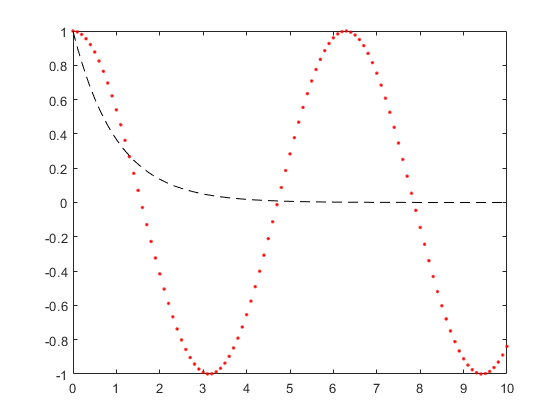

% cos(x) 는 빨간 점으로 그리고 exp(-x)는 검은 점선으로 그리기
plot(x, y1, 'r.', x, y2, 'k--')

## 2. 그래프 서식 설정

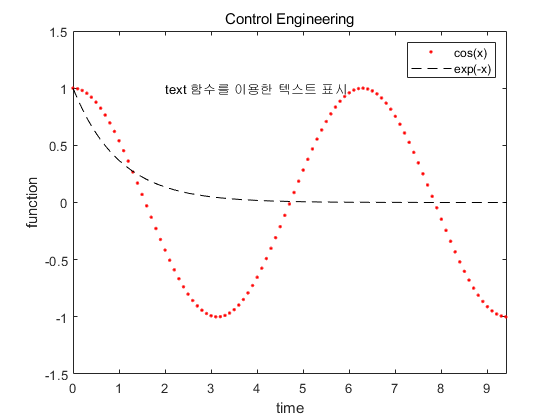

clc; clear
% 모든 figure 창 닫기
close all
x = 0:0.1:10;
y1 = cos(x);
y2 = exp(-x);

% cos(x) 는 빨간 점으로 그리고 exp(-x)는 검은 점선으로 그리기')
plot(x, y1, 'r.', x, y2, 'k--')

% 그래프 속성 표시
% 그래프 위에 제목 붙이기   
title('Control Engineering')

% x, y축 이름 붙이기
xlabel('time')
ylabel('function')

% 그래프 영역 지정
axis([0 pi*3 -1.5 1.5])

% 그래프 안에 텍스트 표시
text(2, 1, 'text 함수를 이용한 텍스트 표시')

% 그래프 각 선에 대한 라벨 표시
legend('cos(x)', 'exp(-x)')

## 3. 그래프 창 관리

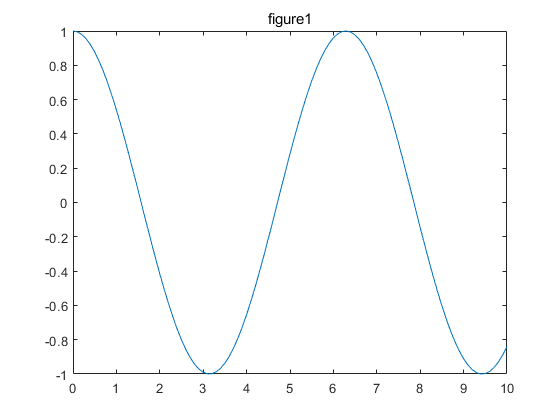

clc; clear
% 모든 figure 창 닫기
close all
x = 0:0.1:10;
y1 = cos(x);
y2 = exp(-x);

% 그래프를 따로 그리면 기존 그래프를 없애고 새로 그리게 됨
plot(x, y1)
title('figure1')

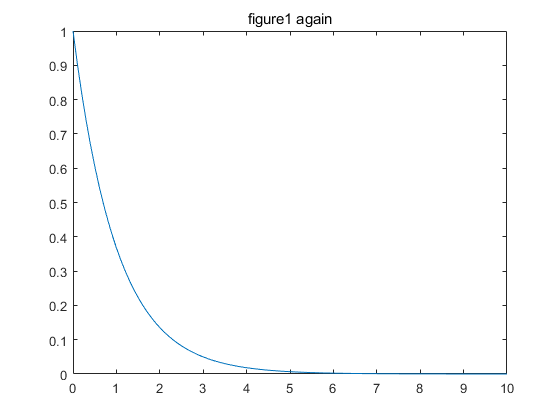

plot(x, y2)
title('figure1 again')

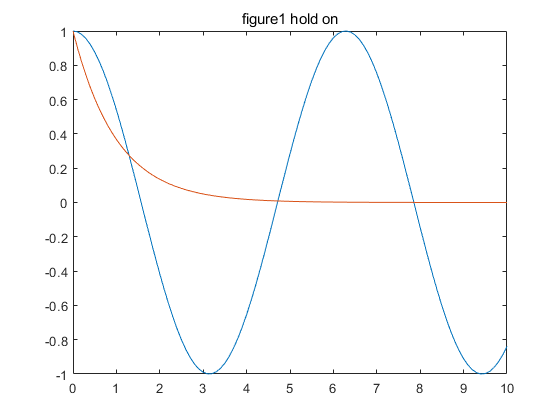

% 기존 그래프 위에 새 그래프를 그리려면 hold on
plot(x, y1)
hold on
plot(x, y2)
title('figure1 hold on')
% 기존 그래프를 지우고 새 그래프를 그리려면 hold off
hold off

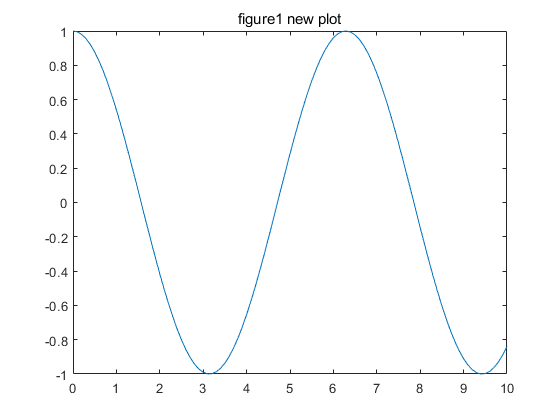

plot(x, y1)
title('figure1 new plot')

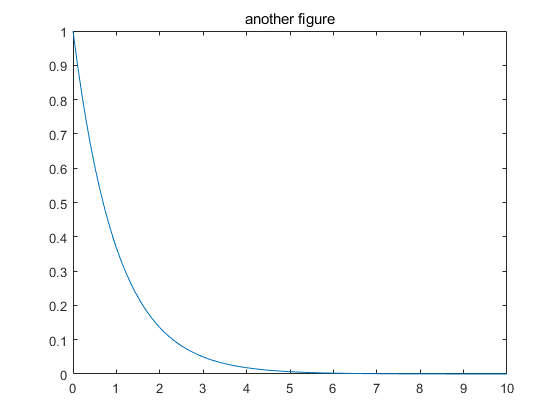

% 새창에 y2 그리려면 figure 함수 이용
figure
plot(x, y2)
title('another figure')

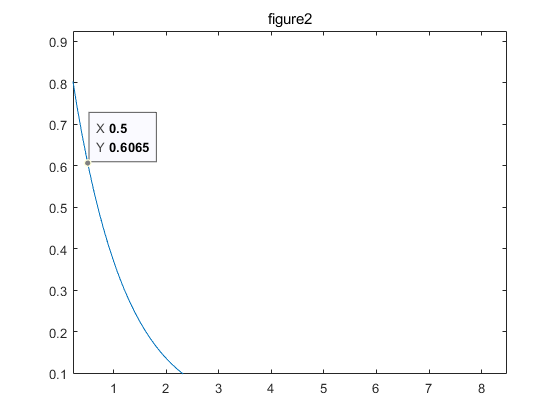

% figure 번호를 명시적으로 지정 가능
figure(2)
plot(x, y2)
title('figure2')

## 4. 창 나누기

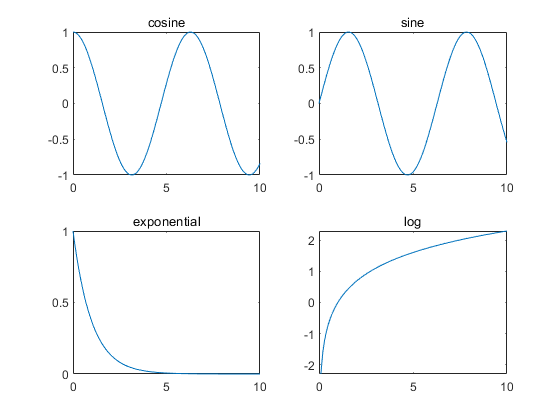

clc; clear;
% 모든 figure 창 닫기
close all
% 데이터 준비
x = 0:0.1:10;
y1 = cos(x);
y2 = sin(x);
y3 = exp(-x);
y4 = log(x);

% figure(1)
subplot(2,2,1)
plot(x, y1)
title('cosine')

subplot(2,2,2)
plot(x, y2)
title('sine')

subplot(2,2,3)
plot(x, y3)
title('exponential')

subplot(2,2,4)
plot(x, y4)
title('log')